## Überblick

% Matlab clearen zum Beginn:
clear
close all

### Einführung

Das Zusammenspiel des Roboters mit der Umgebung lässt sich wie folgt aufteilen. Die Robotersteuerung verarbeitet Sensordaten (Drahtsignalspulen sind innerhalb oder außerhalb des Feldes) und gibt Sollbewegungen an die Fahrmotoren vor (z.B. Geradeausfahren oder Wendemanöver). Die Sollbewegungen resultieren in Bewegungen und werden im Umgebungsmodell abgebildet. Durch die veränderte Position des Mähers resultieren wiederum Änderungen der Sensordaten, die von der Robotersteuerung im nächsten Zeitschritt verarbeitet werden.

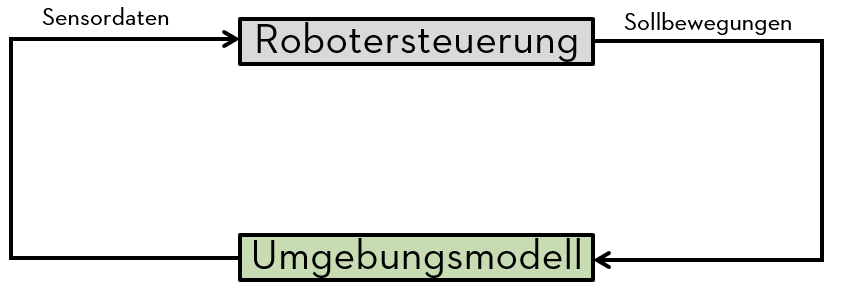

## Umgebungsmodell

Im Umgebungsmodell wird anhand der Vorgabe aus der Robotersteuerung die Bewegung des Geräts modelliert. Die Drahtsensordaten werden anhand der Positionen der Drahtsensoren generiert und dienen der Robotersteuerung als Eingangssignal.

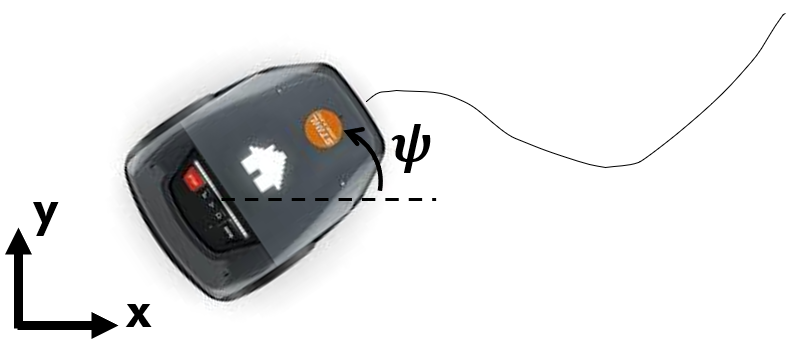

Die Signalkette innerhalb des Umgebungsmodells lässt sich wie folgt darstellen:

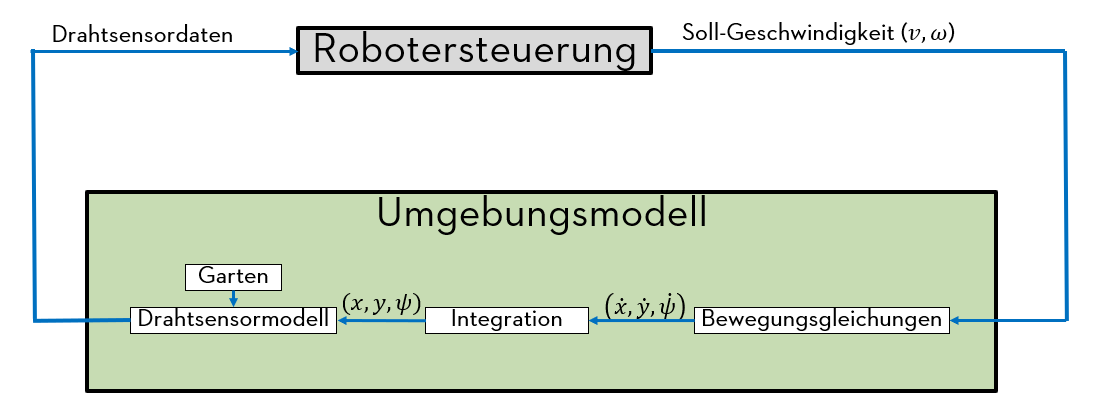

### Annahmen und Systembeschreibung für die mathematische Modellierung

Das **globale Koordinatensystem** der zweidimensionalen Ebene ist mit **X**, **Y** sowie der Verdrehung $\psi \;$definiert.

Die Fortbewegung des Roboters wird mit der** longitudinalen Fahrgeschwindigkeit V** sowie der **Drehrate **$\omega \;$um die Drehachse zwischen den beiden Fahrantrieben beschrieben. Die Robotersteuerung gibt die Soll-Bewegung über V und $\omega \;$vor.

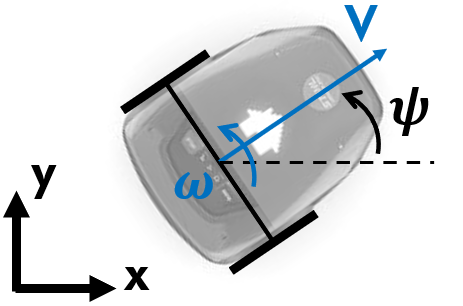

Transformiert ergeben sich folgende Geschwindigkeiten im globalen Koordinatensystem:


$$\begin{array}{l}
\dot{x} \left(t\right)=v\left(t\right)\;\cos \left(\psi \;\left(t\right)\right)\\
\dot{y} \left(t\right)=v\left(t\right)\;\sin \left(\psi \;\left(t\right)\right)\\
\dot{\psi \;} \left(t\right)=\omega \;\left(t\right)
\end{array}$$


### Roboterkontur und Drahtsignalsensorpositionen

Die Roboterkontur und die Drahtsignalsensorpositionen werden im lokalen Koordinatensystem des Roboters definiert.

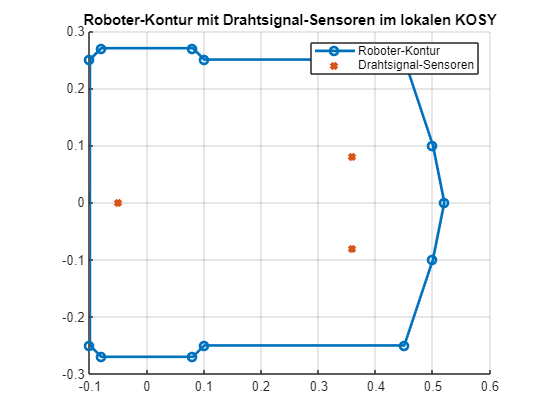

% Mäher-Kontur, definiert im lokalen Koordinatensystem des Roboters:
xMower_local = [-0.1 -0.08 0.08 0.1 0.45 0.5 0.52 0.5 0.45 0.1 0.08 -0.08 -0.1 -0.1];
yMower_local = [-0.25 -0.27 -0.27 -0.25 -0.25 -0.1 0 0.1 0.25 0.25 0.27 0.27 0.25 -0.25];

% Drahtsignalsensor-Positionen, definiert im lokalen Koordinatensystem des Roboters:
xSpulen_local = [0.36 0.36 -0.05];
ySpulen_local = [0.08 -0.08 0];

% Plot Mäher und Spulen im lokalen KOSY
clf
hold on, grid on
daspect([1 1 1])
title('Roboter-Kontur mit Drahtsignal-Sensoren im lokalen KOSY')
plot(xMower_local,yMower_local,'-o','LineWidth',2,'DisplayName','Roboter-Kontur')
plot(xSpulen_local,ySpulen_local,'x','LineWidth',3,'DisplayName','Drahtsignal-Sensoren')
legend()
hold off

### Gartendefinition

Der Garten bzw. der Verlauf des Begrenzungsdrahts wird im globalen Koordinatensystem definiert.

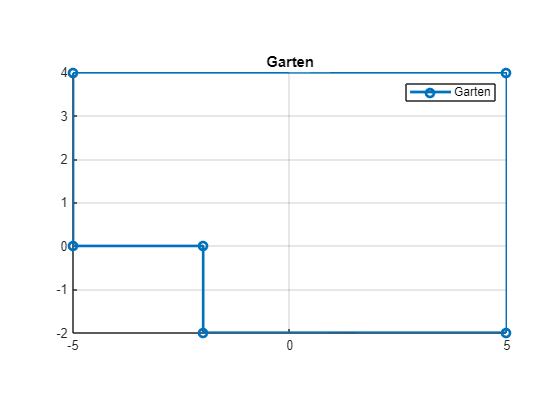

% Garten-Kontur
garden_x = [-2,5,5,-5,-5,-2,-2];
garden_y = [-2,-2,4,4,0,0,-2];
clf
hold on, grid on
daspect([1 1 1])
title('Garten')
plot(garden_x,garden_y,'-o','LineWidth',2,'DisplayName','Garten')
legend()
hold off

### Bewegungsgleichungen und Simulation in Matlab

Im Folgenden wird exemplarisch der Roboter mit den Sensoren im definierten Garten in einem Kreisbogen bewegt. Hierbei werden die Bewegungsgleichungen in Matlab integriert und die Koordinatentransformation von lokal zu global kommt zum Einsatz.

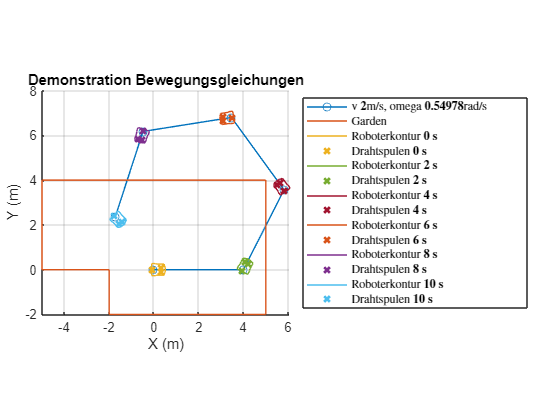

% Betrachteter Zeitraum: 0 bis 10 s, diskretisiert in 2 s -Schritten:
t = 0:2:10;
piinkr = pi/40; 
pidefault = piinkr*4*2;
pimax = pi/2;
pimin = -pi/2;

% Längsgeschwindigkeit v und Drehrate omega des Roboters:
v_const = 2; % in m/s
omega_const = 0.549778714378214; % in rad/s. Mathematisch positiv gegen den UZS.

% v und omega diskretisiert in jedem Zeitschritt. v und omega sind konstant
% über die Zeit:
v = ones(length(t),1) * v_const;
omega = ones(length(t),1) * omega_const;

% Initialzustand des Roboters. Position und Orientierung:
x(1) = 0;
y(1) = 0;
psi(1) = 0;

for i_t = 1:length(t)
% Aufstellen der Bewegungsgleichung:
x_dot(i_t) = v(i_t) * cos(psi(i_t));
y_dot(i_t) = v(i_t) * sin(psi(i_t));
psi_dot(i_t) = omega(i_t);


% Rotations-Matrix für KOSY-Trafo lokal --> global
rotMat = [cos(psi(i_t)) -sin(psi(i_t)); sin(psi(i_t)) cos(psi(i_t))];
xMower(i_t,:) = x(i_t) + rotMat(1,:) * [xMower_local; yMower_local];
yMower(i_t,:) = y(i_t) + rotMat(2,:) * [xMower_local; yMower_local];
xSpulen(i_t,:) = x(i_t) + rotMat(1,:) * [xSpulen_local; ySpulen_local];
ySpulen(i_t,:) = y(i_t) + rotMat(2,:) * [xSpulen_local; ySpulen_local];

% Diskrete Integration: Berechnung des nächsten Zeitschritts
if i_t == length(t) %nächster Zeitschritt nicht mehr benötigt
    break
end
delta_t = t(i_t+1) - t(i_t);
x(i_t+1) = x(i_t) + x_dot(i_t) * delta_t;
y(i_t+1) = y(i_t) + y_dot(i_t) * delta_t;
% y = ode45( lsim
psi(i_t+1) = psi(i_t) + psi_dot(i_t) * delta_t;
end

clf
title('Demonstration Bewegungsgleichungen')
xlabel('X (m)')
% xlim([0 10])
% ylim([-2 2])
ylabel('Y (m)')
hold on, grid on
daspect([1 1 1])
plot(x,y,'-o','DisplayName',['v \textbf{' num2str(v_const) '} m/s, omega \textbf{' num2str(omega_const) '} rad/s'])
plot(garden_x,garden_y,'DisplayName','Garden')

for i_t = 1:length(t)
hh = plot(xMower(i_t,:),yMower(i_t,:),'-','DisplayName',['Roboterkontur \textbf{' num2str(t(i_t)) ' s}']);
plot(xSpulen(i_t,:),ySpulen(i_t,:),'x','LineWidth',2,'Color',hh.Color,'DisplayName',['Drahtspulen \textbf{' num2str(t(i_t)) ' s}'])
end
legend('Interpreter','latex','location','eastoutside')

### Polyshape-Funktionalität: inPolygon

Wenn die Spulenposition innerhalb des Mähbereichs ist, so ist das jeweilige Spulensignal "innerhalb", ansonsten "außerhalb" des Mähbereichs.

Hilfreich könnte die Funktionalität inPolygon sein. Beispielhaft wird eine Kontur definiert und eine Punktewolke. Sind die Punkte innerhalb der Kontur, sollen diese grün geplottet werden, sonst rot.

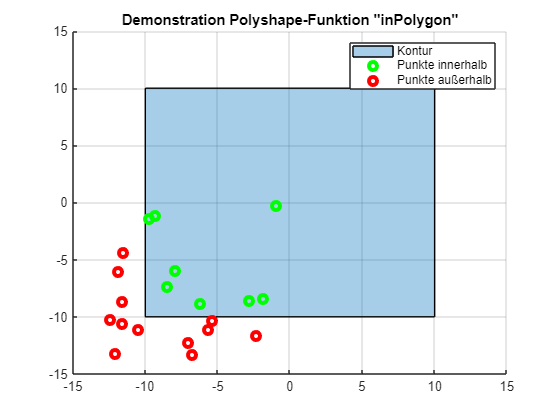

clf
konturX = [-10,10,10,-10];
konturY = [-10,-10,10,10];

punkte_X = rand(20,1)*15-15;
punkte_Y = rand(20,1)*15-15;

title('Demonstration Polyshape-Funktion "inPolygon"')
hold on, grid on
plot(polyshape(konturX,konturY),'DisplayName','Kontur')

i_inside = find(inpolygon(punkte_X,punkte_Y,konturX,konturY));
i_outside = find(~inpolygon(punkte_X,punkte_Y,konturX,konturY));
plot(punkte_X(i_inside),punkte_Y(i_inside),'o','LineWidth',3,'Color',[0 1 0],'DisplayName','Punkte innerhalb')
plot(punkte_X(i_outside),punkte_Y(i_outside),'o','LineWidth',3,'Color',[1 0 0],'DisplayName','Punkte außerhalb')

legend()

## Robotersteuerung

Zustandsautomaten lassen sich in Stateflow (Teil von Simulink) abbilden. Simulink lässt sich in Matlab über den Befehl "simulink" in der Kommandozeile öffnen. Eine Einführung in Simulink erfolgt an späterer Stelle.

Über ein Doppelklick in das Simulink-Fenster und der Eingabe "stateflow" lässt sich ein Stateflow-Chart hinzufügen:

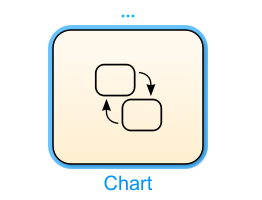

Über den Reiter Modeling lassen sich States hinzufügen:

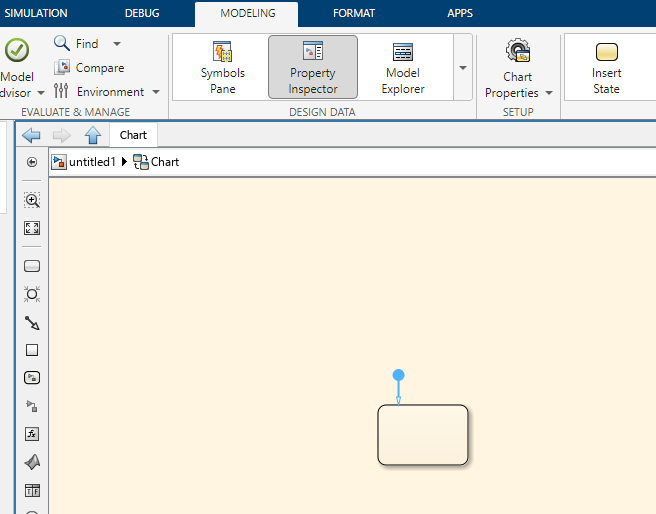

Verschiedene States werden über Transitionen (Bedingungen) miteinander verbunden. In den States werden die Ausgänge gesetzt und in den Bedingungen werden Eingänge verwendet. Über den SymbolsPane werden die Variablen (Ein-, Ausgänge, lokale Variablen) definiert.

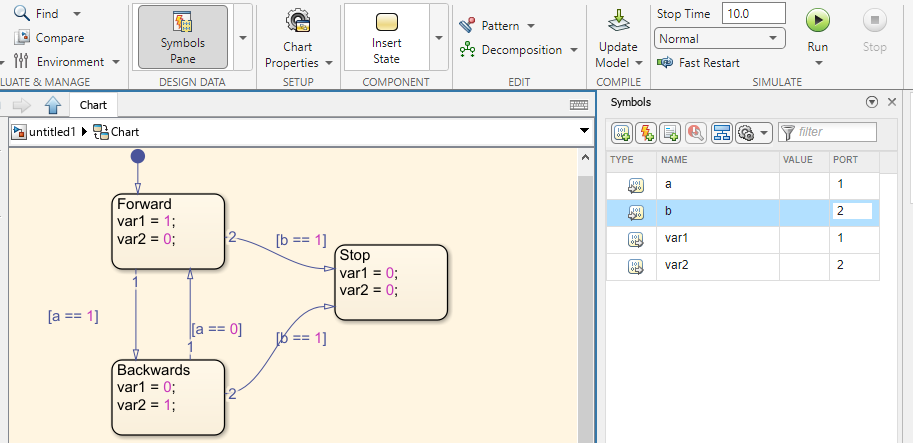

Im Anschluss sind die Ein- und Ausgänge des Stateflow-Charts in Simulink ersichtlich:

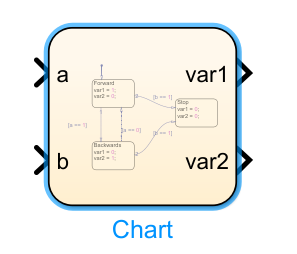

## Simulation

Zunächst wird ein kurzer Überblick über Simulink gegeben. Um die Simulation im Anschluss auswerten zu können, wird eine Methode des Signal-Loggens in Simulink vorgestellt.

### Einführung in Simulink

Simulink ist eine Erweiterung von Matlab und eignet sich hervorragend zum Aufbau von Simulationsumgebungen.

Über Signallinien werden einzelne Blöcke (z.B. Stateflow, Matlab-Functions, mathematische Operationen, ...) miteinander verbinden. Über Doppelklick in die Simulink-Hintergrundfläche lassen sich Blöcke suchen und hinzufügen. Beispielsweise über den Library-Browser lassen sich ansonsten auch Blöcke finden:

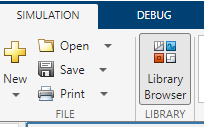

#### Zeitschrittweiten

Standardmäßig ist in Simulink eine variable Zeitschrittweite der Simulation eingestellt. Für Simulationen ist dies vorteilhaft, da somit zu Zeitpunkten mit relevanten Änderungen feiner diskretisiert werden kann (z.B. bei Kollisionen).

Die Robotersteuerung soll jedoch (wie beim echten Roboter) im fixen 10 ms-Takt arbeiten. Um dies zu berücksichtigen, müssen die Schnittstelle von und zur Robotersteuerung jeweils mit Zero-Order-Hold-Blöcken versehen werden. In diesem Block wird die Taktzeit hinterlegt.

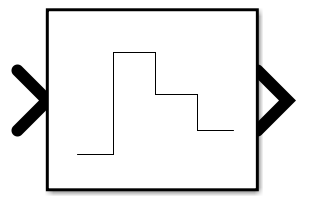

#### Methode um Signale zu loggen in SImulink

Durch Klicken auf einen Signal-Pfeil erscheint ein Menü. Hierbei kann das Signal-Loggen aktiviert werden. Die jeweiligen geloggten Signale sollten durch Doppelklick auf den Signalpfeil benannt werden.

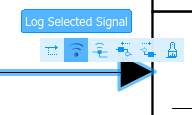

Nach Durchführung der Simulation in Simulink sind die geloggten Signale im Matlab-Workspace unter "out" zugreifbar.

### Ansteuerung von Simulink aus Matlab

Matlab (Auswertungen, Variablen-Definitionen) und Simulink (Simulationsmodell) lassen sich hervorragend gegenseitig ergänzen.

#### Pre Load (Matlab-Workspace)

In der Standardeinstellung kann Simulink auf die Variablen des Matlab-Workspaces zugreifen. Es bietet sich dementsprechend an, vor Ausführung des Simulinkmodells über ein Matlab-Skript Variablen zu definieren und in den Workspace zu laden.

#### Simulation in Simulink

Die Simulation wird über Run gestartet und läuft bis zur eingestellten Simulationsdauer bzw. Stop Time.

#### Post Processing in Matlab

Die geloggten Signale sind nach Simulationsdurchführung im Matlab-Workspace unter "out.logsout" hinterlegt. Durch Matlab-Skripte lassen sich Auswertungen und Plots erstellen.

#### Beispiel: Aufruf von Simulink in Matlab

Die Simulationsdurchführung von Simulink lässt sich auch per Matlab-Aufruf durchführen. Somit ist die komplette Kette (Pre Load, Simulation, Post Processing) in einem Matlab-Skript möglich.

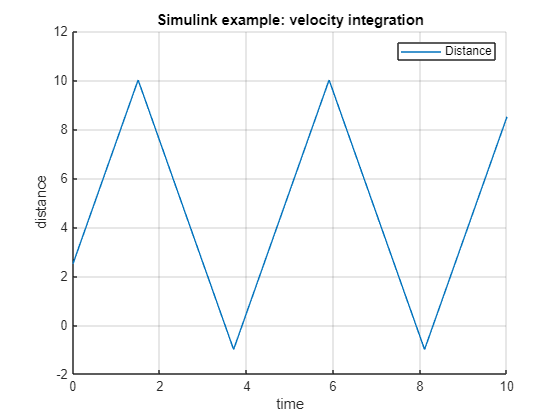

% Pre load:
velocity = 5;
distance0 = 2.5;

% Simulation:
out = sim("SimulinkExampleVelocity");

% Post processing with simulation data (out):
clf
title('Simulink example: velocity integration')
hold on, grid on
plot(out.logsout.getElement('distance').Values.Time,...
    out.logsout.getElement('distance').Values.Data,'DisplayName','Distance')
hold off
% Hinweis: Aufgrund der Abtastzeitpunkte wird geringfügig in den negativen
% Bereich gefahren
xlabel('time')
ylabel('distance')
legend()